# IEEE Signal Processing Cup 2020 - Qualifications

% Team 2 : GMM

## Report

#### Defining the problem

5 normal and 5 abnormal recordings are given as ROS .bag files.

The task is to implement models which will give a prediction wheter each sample in the recording is normal/abnormal based on measurements from .bag files.

#### Visualization:

Images were extracted from "/pylon_camera_node/image_raw" topic, rotated 180 degrees and saved as video files with 4fps framerate.

From extracted videos we see that the recordings come from some UAV, where the normal recordings were made during stable flight without fast movement while abnormal recordings were made during very unstable flight with sudden movements.

#### Preanalysis

Every recording has around hundred mesurements but we don't have class labels.

=> We can't use classic classification.

=> Possible solution: Gaussian Mixture Model

#### Measurement analysis

Based on extracted videos, the following measurements were chosen as relevant for analysis:

"/mavros/global_position/local"

"/mavros/imu/data"

"/mavros/imu/mag"

"/mavros/global_position/compass_hdg"

Time plots and histograms show that the oscillations of some measurements are much larger on abnormal recordings than normal ones.

That means that the derivatives of those signals reach higher absolute values on abnormal recordings, which means that variances of those measurements are larger than on normal recordings so they are deemed as more informative.

Physical quantities that satisfy the above description are orientation, linear velocity, magnetic field and compass heading.

Compass heading was discarded because of correlation with magnetic field.

Their derivatives are angular velocity, linear acceleration (already available from IMU), and derivative of magnetic field.

All values are 3D, so the feature vector is 9D.

#### Feature engineering

We added a "lookBack" - adds k last samples to each sample, allowing the ML algorithm to "look back" in time.

#### Gaussian Mixture Model

Implemented GMM with 2 classes.

A sample is classified as abnormal if its posterior probability of abnormal GMM component is larger from the normal one.

Used regularization, and selected the best regularization parameter on CV set, via hold-out cross-validation.

Models are evaluated via BIC score, along with set constraints:

    0 predicted abnromals from normal set,

    "high" percentage of abnormals from abnormal set.

#### Overview of files:

%     addDerivative      - calculates derivatives of selected columns of the table and adds the derivative columns.
%     extractImages      - Extracts images from a bag object
%     files2bag          - Loads all .bag files from given directory into a cell array of bag objects.
%     gmm2dVisualisation - 2D visualization of a GMM. Draws a contour plot and a surf plot, for every GMM component.
%     gmmFit             - Fits GMM to data. Computes Gaussian mixture model on data Z with given
%                           number of classes and regularization value Lambda.
%     lookBack           - For each row in the input matrix, append k last rows to the right.
%     mapFrames          - Matches IMU measurements with corresponding frames.
%                           Sorts IMU timestamps and measurements into table assigning each measurment
%                           set a serial number of the frame that first comes after
%     splitData          - Split the given data into training, CV and test sets using given percent values for split.

%     tables.mat         - saved data, extracted from the bag files
%     GMM.mat            - saved trained model with parameters for data preprocessing

%     main_GMM_en            - Main program.

%% Implementation Work directories for normal and abnormal data.

clear;

% change if needed
workDirNormal = '03_normal';
workDirAbnormal = '04_abnormal';

## Loading the data

Loading .bag files, selecting relevant measurements and converting into tables.

bagsNormal = files2bag(workDirNormal);
bagsAbnormal = files2bag(workDirAbnormal);

[frameIdxNormal, TimeNormal, TNormal] = mapFrames(bagsNormal);
[frameIdxAbnormal, TimeAbnormal, TAbnormal] = mapFrames(bagsAbnormal);

save temp.mat TNormal TAbnormal -mat

load temp.mat
% Adding derivatives of some values?
tableNormalMagDer = addDerivative(TNormal, 'Mag', {'X', 'Y', 'Z'});
tableAbnormalMagDer = addDerivative(TAbnormal, 'Mag', {'X', 'Y', 'Z'});

tableNormal = removevars(tableNormalMagDer, {'MagX', 'MagY', 'MagZ'});
tableAbnormal = removevars(tableAbnormalMagDer, {'MagX', 'MagY', 'MagZ'});


save tables.mat tableNormal tableAbnormal frameIdxNormal frameIdxAbnormal TimeNormal TimeAbnormal -mat

## Modeling

clear; close all; clc;
load('tables.mat')

## Feature generation

X_normal = tableNormal{:,:};
X_abnormal = tableAbnormal{:,:};

% add lookBack
kLast = 3;      % keep in mind that there are around 3 data samples per frame
X_normal = lookBack(X_normal, kLast);
X_abnormal = lookBack(X_abnormal, kLast);

## Train, CV, Test data split

splitPcg = [70, 0];
[X_normal_train, X_normal_cv, X_normal_test, idx_normal_train, idx_normal_cv, idx_normal_test] = splitData(X_normal, splitPcg);
[X_abnormal_train, X_abnormal_cv, X_abnormal_test, idx_abnormal_train, idx_abnormal_cv, idx_abnormal_test] = splitData(X_abnormal, splitPcg);

X_train = [X_normal_train; X_abnormal_train];
X_cv = [X_normal_cv; X_abnormal_cv];
X_test = [X_normal_test; X_abnormal_test];

M = size(X_train, 1);
M_normal = size(X_normal_train, 1);
M_abnormal = size(X_abnormal_train, 1);

## Feature mapping (scaling and normalization)

mu = 0; %mean(X_train);
% Sigma = cov(X_train);
scalingFactor = 10^(-5);

X_train_mapped = (X_train - mu) * scalingFactor;

## PCA

[coeff,score,latent,tsquared,explained,mu_pca] = pca(X_train_mapped);

varianceRetained = 99;
numComponents = find(cumsum(explained) >= varianceRetained, 1);

U = coeff(:,1:numComponents);

Z = (X_train_mapped - mu_pca)* U;

save Z.mat Z -mat

## Training data vizualization

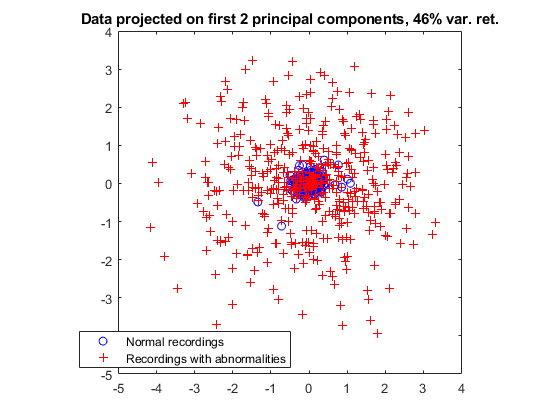

y = [zeros(M_normal,1); ones(M_abnormal,1)];
figure
    gscatter(Z(:,1), Z(:,2), y, 'br', 'o+');
    legend('Normal recordings','Recordings with abnormalities');
    title(['Data projected on first 2 principal components, ' int2str(sum(explained(1:2))) '% var. ret.'])
    axis square


disp(['Number of principal components with ' int2str(varianceRetained) '% variance retained: '...
    int2str(numComponents) '/' int2str(size(X_train, 2))]);

Number of principal components with 99% variance retained: 11/36


## Gaussian Mixture Model

load Z.mat
numClasses = 2;
% max_eval = 0;
min_AIC = inf;
Iterations = 1000;
Lambdas = 0.05 : 0.0005 : 0.1; % nice for kLast = 3;
% Lambdas = 0.02 : 0.0005 : 0.06; % nice for kLast = 5,6;

for Lambda = Lambdas
    disp(['Lambda = ' num2str(Lambda)]);
    [GMM, labelName, normal, abnormal, middle] = gmmFit(Z, numClasses, Lambda, Iterations);
    eval = GMM.AIC;
        
    % prediction
    P_test = posterior(GMM, Z);
    [~, y_pred] = max(P_test, [], 2);
    
    n_an = nnz(y_pred(1:M_normal) == abnormal);
    n_aa = nnz(y_pred(M_normal+1 : end) == abnormal);

    % the percentage of predicted abnormals from normal set should be 0,
    % the percentage of predicted abnormals from abnormal set should be high,
    if (n_an/M_normal > 0) || (n_aa/M_abnormal < 0.66)
        eval = inf;
    end
    disp(['Evaluation (smaller is better): ' num2str(eval)])
    
    if eval < min_AIC
        min_AIC = eval;
        GMM_opt = GMM;
        Lambda_opt = Lambda;
        normal_opt = normal;
        abnormal_opt = abnormal;
        labelName_opt = labelName;
    end
    
end

Lambda = 0.05


Evaluation (smaller is better): Inf


Lambda = 0.0505


Evaluation (smaller is better): Inf


Lambda = 0.051


Evaluation (smaller is better): Inf


Lambda = 0.0515


Evaluation (smaller is better): Inf


Lambda = 0.052


Evaluation (smaller is better): Inf


Lambda = 0.0525


Evaluation (smaller is better): Inf


Lambda = 0.053


Evaluation (smaller is better): 9343.7506


Lambda = 0.0535


Evaluation (smaller is better): 9383.0003


Lambda = 0.054


Evaluation (smaller is better): 9421.8806


Lambda = 0.0545


Evaluation (smaller is better): 9460.344


Lambda = 0.055


Evaluation (smaller is better): 9498.3662


Lambda = 0.0555


Evaluation (smaller is better): 9535.9207


Lambda = 0.056


Evaluation (smaller is better): 9573.0137


Lambda = 0.0565


Evaluation (smaller is better): Inf


Lambda = 0.057


Evaluation (smaller is better): Inf


Lambda = 0.0575


Evaluation (smaller is better): Inf


Lambda = 0.058


Evaluation (smaller is better): Inf


Lambda = 0.0585


Evaluation (smaller is better): Inf


Lambda = 0.059


Evaluation (smaller is better): Inf


Lambda = 0.0595


Evaluation (smaller is better): Inf


Lambda = 0.06


Evaluation (smaller is better): Inf


Lambda = 0.0605


Evaluation (smaller is better): Inf


Lambda = 0.061


Evaluation (smaller is better): Inf


Lambda = 0.0615


Evaluation (smaller is better): Inf


Lambda = 0.062


Evaluation (smaller is better): Inf


Lambda = 0.0625


Evaluation (smaller is better): Inf


Lambda = 0.063


Evaluation (smaller is better): Inf


Lambda = 0.0635


Evaluation (smaller is better): Inf


Lambda = 0.064


Evaluation (smaller is better): Inf


Lambda = 0.0645


Evaluation (smaller is better): Inf


Lambda = 0.065


Evaluation (smaller is better): Inf


Lambda = 0.0655


Evaluation (smaller is better): Inf


Lambda = 0.066


Evaluation (smaller is better): Inf


Lambda = 0.0665


Evaluation (smaller is better): Inf


Lambda = 0.067


Evaluation (smaller is better): Inf


Lambda = 0.0675


Evaluation (smaller is better): Inf


Lambda = 0.068


Evaluation (smaller is better): Inf


Lambda = 0.0685


Evaluation (smaller is better): Inf


Lambda = 0.069


Evaluation (smaller is better): Inf


Lambda = 0.0695


Evaluation (smaller is better): Inf


Lambda = 0.07


Evaluation (smaller is better): Inf


Lambda = 0.0705


Evaluation (smaller is better): Inf


Lambda = 0.071


Evaluation (smaller is better): Inf


Lambda = 0.0715


Evaluation (smaller is better): Inf


Lambda = 0.072


Evaluation (smaller is better): Inf


Lambda = 0.0725


Evaluation (smaller is better): Inf


Lambda = 0.073


Evaluation (smaller is better): Inf


Lambda = 0.0735


Evaluation (smaller is better): Inf


Lambda = 0.074


Evaluation (smaller is better): Inf


Lambda = 0.0745


Evaluation (smaller is better): Inf


Lambda = 0.075


Evaluation (smaller is better): Inf


Lambda = 0.0755


Evaluation (smaller is better): Inf


Lambda = 0.076


Evaluation (smaller is better): Inf


Lambda = 0.0765


Evaluation (smaller is better): Inf


Lambda = 0.077


Evaluation (smaller is better): Inf


Lambda = 0.0775


Evaluation (smaller is better): Inf


Lambda = 0.078


Evaluation (smaller is better): Inf


Lambda = 0.0785


Evaluation (smaller is better): Inf


Lambda = 0.079


Evaluation (smaller is better): Inf


Lambda = 0.0795


Evaluation (smaller is better): Inf


Lambda = 0.08


Evaluation (smaller is better): Inf


Lambda = 0.0805


Evaluation (smaller is better): Inf


Lambda = 0.081


Evaluation (smaller is better): Inf


Lambda = 0.0815


Evaluation (smaller is better): Inf


Lambda = 0.082


Evaluation (smaller is better): Inf


Lambda = 0.0825


Evaluation (smaller is better): Inf


Lambda = 0.083


Evaluation (smaller is better): Inf


Lambda = 0.0835


Evaluation (smaller is better): Inf


Lambda = 0.084


Evaluation (smaller is better): Inf


Lambda = 0.0845


Evaluation (smaller is better): Inf


Lambda = 0.085


Evaluation (smaller is better): Inf


Lambda = 0.0855


Evaluation (smaller is better): Inf


Lambda = 0.086


Evaluation (smaller is better): Inf


Lambda = 0.0865


Evaluation (smaller is better): Inf


Lambda = 0.087


Evaluation (smaller is better): Inf


Lambda = 0.0875


Evaluation (smaller is better): Inf


Lambda = 0.088


Evaluation (smaller is better): Inf


Lambda = 0.0885


Evaluation (smaller is better): Inf


Lambda = 0.089


Evaluation (smaller is better): Inf


Lambda = 0.0895


Evaluation (smaller is better): Inf


Lambda = 0.09


Evaluation (smaller is better): Inf


Lambda = 0.0905


Evaluation (smaller is better): Inf


Lambda = 0.091


Evaluation (smaller is better): Inf


Lambda = 0.0915


Evaluation (smaller is better): Inf


Lambda = 0.092


Evaluation (smaller is better): Inf


Lambda = 0.0925


Evaluation (smaller is better): Inf


Lambda = 0.093


Evaluation (smaller is better): Inf


Lambda = 0.0935


Evaluation (smaller is better): Inf


Lambda = 0.094


Evaluation (smaller is better): Inf


Lambda = 0.0945


Evaluation (smaller is better): Inf


Lambda = 0.095


Evaluation (smaller is better): Inf


Lambda = 0.0955


Evaluation (smaller is better): Inf


Lambda = 0.096


Evaluation (smaller is better): Inf


Lambda = 0.0965


Evaluation (smaller is better): Inf


Lambda = 0.097


Evaluation (smaller is better): Inf


Lambda = 0.0975


Evaluation (smaller is better): Inf


Lambda = 0.098


Evaluation (smaller is better): Inf


Lambda = 0.0985


Evaluation (smaller is better): Inf


Lambda = 0.099


Evaluation (smaller is better): Inf


Lambda = 0.0995


Evaluation (smaller is better): Inf


Lambda = 0.1


Evaluation (smaller is better): Inf



GMM = GMM_opt;
Lambda = Lambda_opt;
normal = normal_opt;
abnormal = abnormal_opt;
labelName = labelName_opt;
disp(['Optimal Lambda is:' num2str(Lambda_opt)]);

Optimal Lambda is:0.053


## Evaluate on test set

% feature maping and dim. reduction
Z_test = ((X_test - mu)*scalingFactor - mu_pca) * U;

% prediction
P_test = posterior(GMM, Z_test);
[~, y_test] = max(P_test, [], 2);

## Visualize predicitons

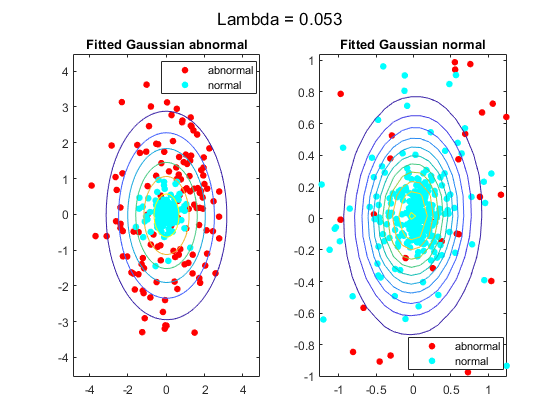

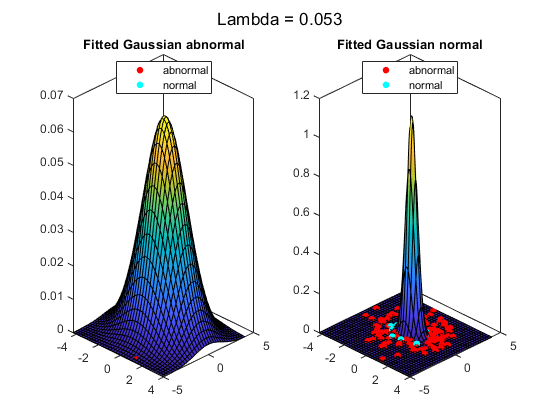

% gmm2dVisualization(GMM, Z, y, labelName, Lambda);
gmm2dVisualization(GMM, Z_test, y_test, labelName, Lambda);

disp(['Optimal Lambda is:' num2str(Lambda_opt)]);

Optimal Lambda is:0.053


## Some statistics

disp(['For Lambda:' num2str(Lambda)]);

For Lambda:0.053



M_pred = [nnz(y_test == normal), nnz(y_test == abnormal)];
M_test = [length(X_normal_test), length(X_abnormal_test)];

M_pred_conf = [nnz(y_test(1:M_test(1)) == normal), nnz(y_test(1:M_test(1)) == abnormal);...
               nnz(y_test(M_test(1)+1:end) == normal), nnz(y_test(M_test(1)+1:end) == abnormal)];

disp(['Num samples normal: ' int2str(M_test(1))])

Num samples normal: 207


disp(['Num samples abnormal: ' int2str(M_test(2))])

Num samples abnormal: 212



disp(['Num predicted normal: ' int2str(M_pred(normal))])

Num predicted normal: 136


disp(['Num predicted abnormal: ' int2str(M_pred(abnormal))])

Num predicted abnormal: 283



disp(['Num predicted normal from normal set: ' int2str(M_pred_conf(1,1))])

Num predicted normal from normal set: 207


disp(['Num predicted abnormal from normal set: ' int2str(M_pred_conf(1,2))])

Num predicted abnormal from normal set: 0


disp(['Num predicted normal from abnormal set: ' int2str(M_pred_conf(2,1))])

Num predicted normal from abnormal set: 76


disp(['Num predicted abnormal from abnormal set: ' int2str(M_pred_conf(2,2))])

Num predicted abnormal from abnormal set: 136


## Time visualization

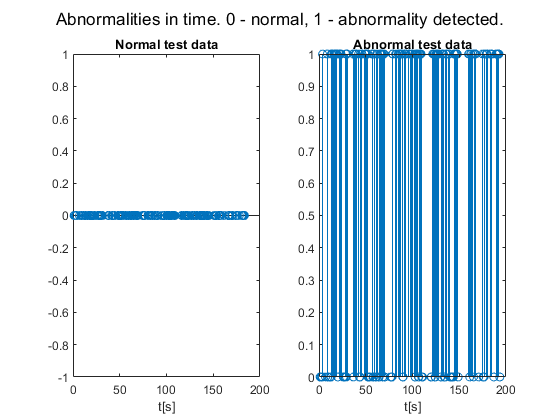

n_normal_normal = kLast + idx_normal_test(y_test(1:M_test(1)) == normal);
n_normal_abnormal = kLast + idx_normal_test(y_test(1:M_test(1)) == abnormal);
n_abnormal_normal = kLast + idx_abnormal_test(y_test(M_test(1)+1:end) == normal);
n_abnormal_abnormal = kLast + idx_abnormal_test(y_test(M_test(1)+1:end) == abnormal);

n_normal = [n_normal_normal n_normal_abnormal];
n_abnormal = [n_abnormal_normal n_abnormal_abnormal];

t_normal = TimeNormal{n_normal,1};
t_abnormal = TimeAbnormal{n_abnormal,1};

y_normal = [zeros(M_pred_conf(1,1), 1); ones(M_pred_conf(1,2), 1)];
y_abnormal = [zeros(M_pred_conf(2,1), 1); ones(M_pred_conf(2,2), 1)];

figure
    subplot(1,2,1)
        stem(t_normal, y_normal);
        title('Normal test data');
        xlabel('t[s]')
    
    subplot(1,2,2)
        stem(t_abnormal, y_abnormal);
        title('Abnormal test data');
        xlabel('t[s]')
    
    sgtitle('Abnormalities in time. 0 - normal, 1 - abnormality detected.');

## Frames:

% unique(frameIdxAbnormal{sort(n_normal_normal), 1})
unique(frameIdxAbnormal{sort(n_normal_abnormal), 1})


ans =

  0×1 empty double column vector



% unique(frameIdxAbnormal{sort(n_abnormal_normal), 1})
unique(frameIdxAbnormal{sort(n_abnormal_abnormal), 1})

ans =      7
    13
    20
    21
    23
    25
    26
    27
    28
    32


## Saving the model

save GMM.mat GMM mu scalingFactor mu_pca U -mat
%